# Polære koordinater

                        

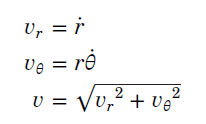                    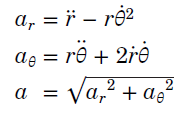

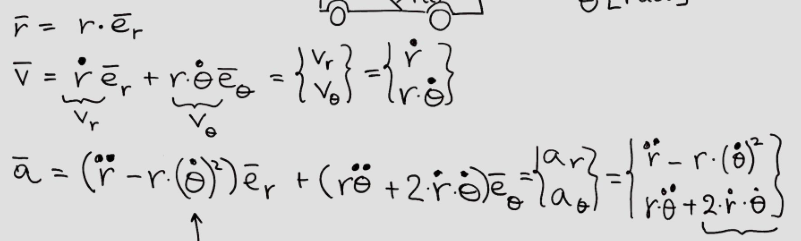

Hvis r er konstant

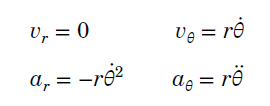

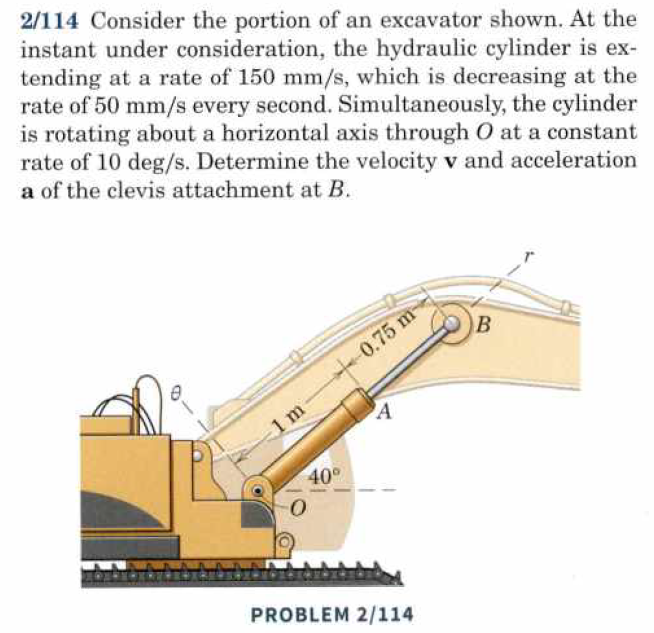

clear

% Opgavens info

% Armen
r = 1.75; % armens længde
r1 = 0.150; % r_prik i m/s. det er armens hastighed
r2 = -0.050; % r_prik_prik i mm/s^2. Det er armens deacceleration


% Vinklen
theta = deg2rad(40); % start vinkel
theta1 = deg2rad(10) % vinkelhastighed, som er konstant, - theta_prik

theta1 = 0.1745

theta2 = 0;           % vinkelaccel = 0 da theta2 er konstant

% Formler til udregning af vinkel- og armhastighed samt accel
v_r = r1;
v_theta = r*theta1;
v = [v_r; v_theta]

v =     0.1500
    0.3054




a_r = r2 - r*theta1^2;
a_theta = r*theta2 + 2*r1*theta1;
a = [a_r; a_theta]

a =    -0.1033
    0.0524


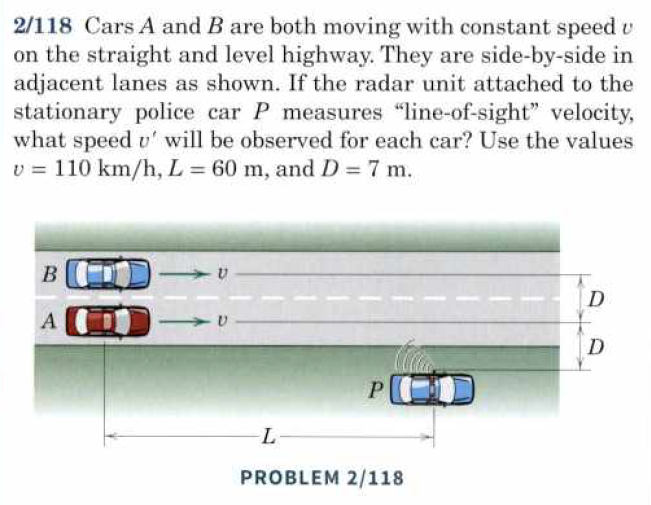

clear

% Opgavens info

% Armen
L = 60;
D = [7,14];

r = sqrt(L^2 + D.^2); % armens længde

r1 = 110; % r_prik i m/s. det er armens hastighed
r2 = 0; % r_prik_prik i mm/s^2. Det er armens deacceleration


% Vinklen
vinkel = atan(D./L)

vinkel =     0.1161    0.2292


theta = deg2rad(vinkel); % start vinkel
theta1 = 0 % vinkelhastighed, som er konstant, - theta_prik

theta1 = 0

theta2 = 0;           % vinkelaccel = 0 da theta2 er konstant

% Formler til udregning af vinkel- og armhastighed samt accel
v_r = cos(vinkel)*r1;
v_theta = r*theta1;
v = [v_r; v_theta]

v =   109.2589  107.1225
         0         0




a_r = r2 - r*theta1^2;
a_theta = r*theta2 + 2*r1*theta1;
a = [a_r; a_theta]

a =      0     0
     0     0


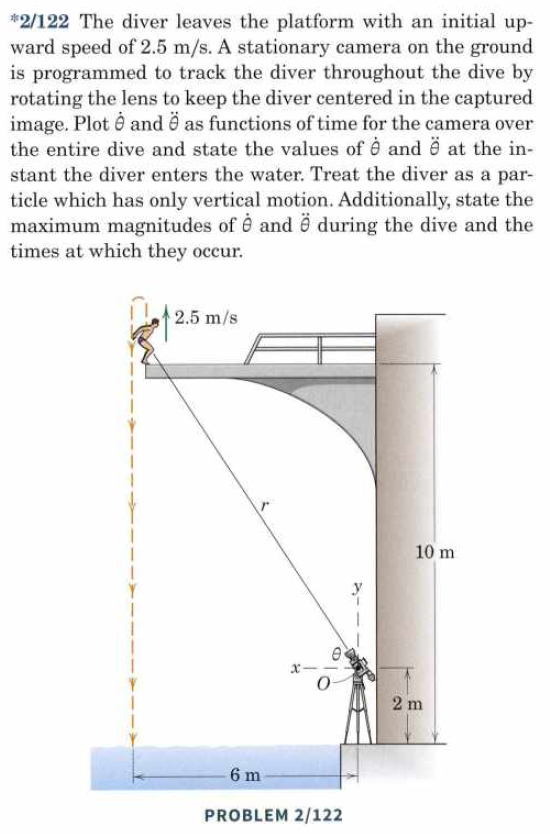

clear


% initial conditions
g = -9.81;
% Distancer fra kamera

x0 = 6;  % x-distancen fra kamera til mand
y0 = 8; % y-distancen fra kamera til mand
ys = -2;
r = sqrt(y0^2 + x0^2); % Armen fra kamera til mand
vinkel = atan(y0/x0); % vinkel mellem arm og kameraets x-akse
rad2deg(vinkel)

ans = 53.1301

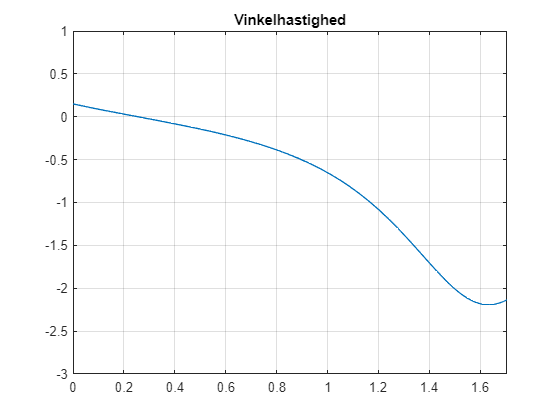

% mandens pos undersøges
v0 = 2.5;

syms t

y = 1/2*g*t^2 + v0*t + y0 == ys; % placeringsligningen
vy = v0 + g*t;

% Der løses for tiden i placeringsligningen
tid = vpa(max(solve(y,t)),4);

% Vinkelhastighed og acceleration
y_tot = 1/2*g*t^2 + v0*t + y0;
theta = atan(y_tot/x0);
theta1 = matlabFunction(diff(theta, t));
theta2 = matlabFunction(diff(theta1, t));

int = [0, double(tid)];


fplot(theta1, int) , ylim([-3, 1]), grid(), title("Vinkelhastighed")

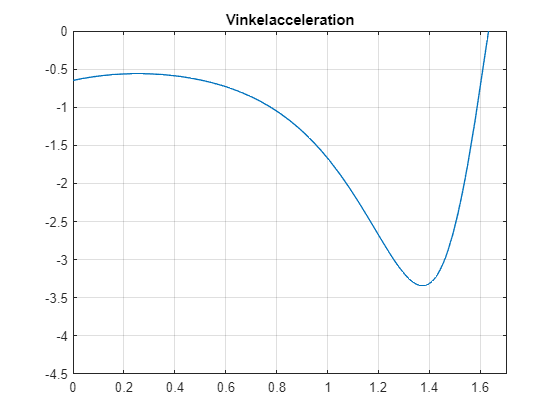

fplot(theta2, int), ylim([-4.5, 0]), grid(), title("Vinkelacceleration")



% Max værdier findes
tlin = linspace(0, double(tid), 1000);

[theta1m, t1m] = max(abs(theta1(tlin)));
theta1m

theta1m = 2.1927

t1m = tlin(t1m)

t1m = 1.6318

[theta2m, t2m] = max(abs(theta2(tlin)));
theta2m

theta2m = 3.3414

t2m = tlin(t2m)

t2m = 1.3741

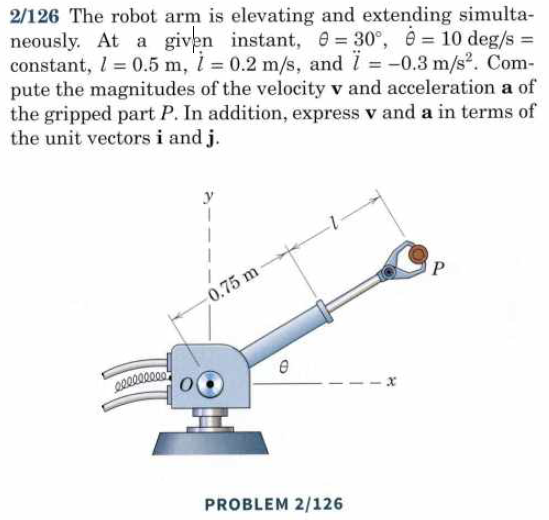

clear
syms i j
vec = [i;j];

% Armen
r = 1.25;    % armens længde
r1 = 0.2;  % r_prik i m/s. det er armens hastighed
r2 = -0.30; % r_prik_prik i mm/s^2. Det er armens deacceleration


% Vinklen
theta = deg2rad(30);  % start vinkel
theta1 = deg2rad(10);  % vinkelhastighed, som er konstant, - theta_prik
theta2 = 0;           % vinkelaccel = 0 da theta2 er konstant

% Formler til udregning af vinkel- og armhastighed samt accel
v_r = r1;
v_theta = r*theta1;
v = vpa([v_r; v_theta].*vec,3)

$$v = \left(\begin{array}{c} 0.2\,i\\ 0.218\,j \end{array}\right)$$


v_tot = sqrt(v_r^2 + v_theta^2)

v_tot = 0.2960



a_r = r2 - r*theta1^2;
a_theta = r*theta2 + 2*r1*theta1;
a = vpa([a_r; a_theta].*vec,3)

$$a = \left(\begin{array}{c} -0.338\,i\\ 0.0698\,j \end{array}\right)$$


a_tot = sqrt(a_r^2 + a_theta^2)

a_tot = 0.3452


% Punktet P's hastighed og accel
p_vr = v_r*(i*cos(theta) + j*sin(theta));
p_vt = v_theta*(-i*cos(theta) + j*sin(theta)); % rotationsretningen gør i negativ

p_v_tot = vpa(p_vr + p_vt, 3)

$$p\_v\_tot = 0.209\,j-0.0157\,i$$



p_ar = a_r*(i*cos(theta) + j*sin(theta));
p_at = a_theta*(-i*sin(theta) + j*cos(theta)); % rotationsretningen gør i negativ

p_a_tot = vpa(p_ar + p_at, 3)

$$p\_a\_tot = -0.328\,i-0.109\,j$$

% clear
% 
% % Opgavens info
% 
% % Armen
% r = 1.75;    % armens længde
% r1 = 0.150;  % r_prik i m/s. det er armens hastighed
% r2 = -0.050; % r_prik_prik i mm/s^2. Det er armens deacceleration
% 
% 
% % Vinklen
% theta = deg2rad(40);  % start vinkel
% theta1 = deg2rad(10)  % vinkelhastighed, som er konstant, - theta_prik
% theta2 = 0;           % vinkelaccel = 0 da theta2 er konstant
% 
% % Formler til udregning af vinkel- og armhastighed samt accel
% v_r = r1;
% v_theta = r*theta1;
% v = [v_r; v_theta]
% 
% 
% a_r = r2 - r*theta1^2;
% a_theta = r*theta2 + 2*r1*theta1;
% a = [a_r; a_theta]
% 
% function noget = Polar(r,r1,r2,v,v1,v2,v3,vr,vv,ar,av)
% %r =  armens længde
% %r1 = r_prik i m/s. det er armens hastighed
% %r2 = r_prik_prik i mm/s^2. Det er armens deacceleration
% 
% 
% % Vinklen
% % v =  start vinkel
% % v1 = vinkelhastighed, som er konstant, - theta_prik
% % v2 = vinkelaccel = 0 da theta2 er konstant
% 
% vr = r1;
% vv = r*v1;
% 
% ar = r2 - r*v1^2;
% av = r*v2 + 2*r1*v1;







